# Dynamic Structural Econometrics -- Auction estimation

Prepared by[Aaron Barkley, University of Melbourne](https://sites.google.com/site/aaronmbarkley)

## 1. Model of first-price sealed-bid auctions

The basic setup for a first-price sealed-bid auction is the following:

- Single seller selling one non-divisible item.  

- A set of $\mathcal{N}=1,2,...,N$ bidders, with $N \geq 2$.

-  Each bidder $n$ has a value $v_n$ for the object. $v_n$ is private information to bidder $n$: bidders only know their own value, not anyone else's.

- Bidders submit a single bid $b_n$, and the highest bidder is awarded the object.

- Expected profit is given by $E[\pi(b_n) | v_n] = \mbox{Pr}(b_n > b_i \ \forall i \not=n) \times (v_n - b_n)$, which is the product of the winning probability for a bid level $b_n$ and the bidder's surplus if that bid wins.

**Independent private values and common values**

We assume that bidders have **independent private values (IPV)**, which means that (i) all bidder valuation draws $v_n$ are i.i.d. draws from the same distribution $F$, and (ii) these valuations are private and individual-specific. The second component rules out scenarios where the object has a common value to all bidders, but the bidders may not be fully informed as to this value. This would be called a **common value** auction, which we won't study here. 

Private values will describe things like art sales, where individuals may have very different preferences over individual art pieces, how those pieces match the other art owned by the bidder, and the bidder's access to funds to bid for the piece. All of these things are individual-specific and will alter the maximum amount someone is willing to bid. An example of a common value framework would be drilling rights for oil. Governments often sell mineral/drilling rights for parcels of land via auction. Firms bidding in these auctions want to extract the oil beneath the ground and sell it. Firms may have different beliefs about the value of drilling in a particular spot, due to differences in geological survey techniques or other reasons. However, the oil is worth the exact same amount to whichever firm pulls it out of the ground. 

A quick thought experiment to get the intuition for whether a scenario is better described by independent private values of common values is the following: if I were to know exactly how much another bidder was willing to pay, would that make me change the maximum amount that I was willing to pay? If the answer is no, then it is likely an IPV scenario: valuations are completely private and unique to each person. If the answer is yes, then there is likely some common component: the other bidder whose valuation I learned may know something about the common value, and I should revise my maximum bid accordingly.

**Equilibrium in first-price sealed-bid auctions**

Bidders participating in the auction will want to choose their bids to maximize their expected payoff:


$$B_n = \arg \max_{b_n} E[\pi(b_n) | v_n] = \mbox{Pr}(b_n > b_i \ \forall i \not=n) \times (v_n - b_n)$$


The payoffs depend on the bids of all the other $n-1$ bidders through the winning probability $\mbox{Pr}(b_n > b_i \ \forall \ i \not= n)$. Therefore, this requires a game-theoretic solution concept to solve, as we must jointly determine the bidding strategies of all $n$ bidders so that they are all mutually best responding. In theory, multiple Nash equilibria exist. In practice, we tend to focus on a specific equilibrium that has two intuitive properties:

- **Symmetry. **Two bidders with the same valuation should submit the same bid: $b_i(v) = b_j(v)$ for all $i,j \in \mathcal{N}$.

- **Monotonicity. **Bids should be increasing in the bidder's valuation: $b_i(v') > b_i(v)$ for all $v', v$ such that $v' > v$.

With these two restrictions in place, we can show that the unique, pure-strategy equilibrium is characterized by a bid function given by


$$b_n(v_n) = v_n - \frac{\int_{r}^{v_n} F(u)^{N-1} du}{F(v_n)^{N-1}}$$


where recall that $F$ is the cdf of bidders' valuations and $r$ is the *reserve price*, or the minimum accepted bid by the seller. For now, we can set $r=0$. We can think of the equilibrium bidding strategy as a "value minus markup" formulation. The bidder takes their valuation $v_n$ and subtracts off an amount given by $\frac{\int_{r}^{v_n} F(u)^{N-1} du}{F(v_n)^{N-1}}$. This "markup" term is increasing in $v_n$, so that bidders with higher valuations will try to get a higher surplus. It is also decreasing in $N$, meaning that more competition means that bidders have to obtain smaller markups. 

With a bit of algebra, we can also re-formulate the equilibrium bid function as a conditional expectation:


$$b_n(v_n) = E\left[ v^{(n-1)} \ | \ v_n > v^{(n-1)} \right]$$


where $v^{(k)}$ denotes the $k$-th order statistic, or the $k$-th smallest observation. This formulation means that each bidder submits a bid equal to the expected value of the second highest bidder, conditional on their valuation being the highest. This makes sense from an equilibrium standpoint. Because equilibrium bidding strategies are monotone, bidders can only win if they have the highest valuation, so when they submit their bid they should assume that their valuation is the highest, as otherwise their bid is irrelevant. So, assuming their bid is the highest, what is the equilibrium bidding strategy? Suppose that the bidder observes all other bidders' valuations. The only equilibrium bid in that case would be for the highest valuation bidder to bid exactly the second highest bidder's valuation: if they bid more than this, they are leaving money on the table, and if they bid less than this, the second-highest valuation bidder can "steal" the auction. The equilibrium bid function does the same thing but for the *expected* second-highest valuation. That is, each bidder will assume that their valuation is the highest and will bid the best guess for the second-highest valuation (conditional on theirs being the highest). 

## 2. Simulate auction data

First, let's define parameters of the bidder valuation distribution. We will work within the hypothetical framework of housing sales, where potential buyers bid for homes in an auction (as is common in much of Australia).

mu_b = 7.5; % Average bidder's home valuation, in $100,000's.
sigma_b = 0.75; % Standard deviation of bidder valuation distribution.
BuyerValueDist = makedist('Normal','mu',mu_b,'sigma',sigma_b); % Assume a normal distribution for valuations

num_auc = 1000; % Simulate 1000 auctions
N=5; % Assume five bidders at each auction
rng(2022); % Fix the random number generator seed so we can reproduce everything exactly.

Now we need to simulate auction outcomes. Learning how to simulate the auction results is useful for performing counterfactual analysis, as after we have changed the model so according to a specific policy experiment, we will have to solve and simulate the endogenous variables to see the policy's effects. Recall that in first-price sealed-bid auctions, each bidder's equilibrium bid, as a function of her valuation, is given by


$$b_n(v_n) = v_n - \frac{\int_{r}^{v_n} F(u)^{N-1} du}{F(v_n)^{N-1}}$$


To implement this in Matlab, we define a function that maps valuations into bids, assuming that the reserve rate $r$ is equal to zero:

% Equilibrium bid function:
B = @(V) arrayfun(@(v) v - ((1./cdf(BuyerValueDist,v)).^(N-1)).*integral(@(u)cdf(BuyerValueDist,u).^(N-1),0,v),V);
% Draw valuations from the distribution defined above:
value_draws = random(BuyerValueDist,[num_auc,N]);
% Get bids from the bidding fuction using the valuation draws:
bids = B(value_draws(:));

% Note: we use the "arrayfun" command above to enable us to pass a vector to the user-made function. We can also write a simpler
% function like this:
% B = @(v) v - ((1./cdf(BuyerValueDist,v)).^(N-1)).*integral(@(u)cdf(BuyerValueDist,u).^(N-1),0,v);
% and use a "for" loop to pass a single valuation into B at a time.

Now we have a set of valuations and bids. If we've done this correctly, we expect that the bids should be below the valuations, and that the gap between the two gets larger as the valuation gets higher.

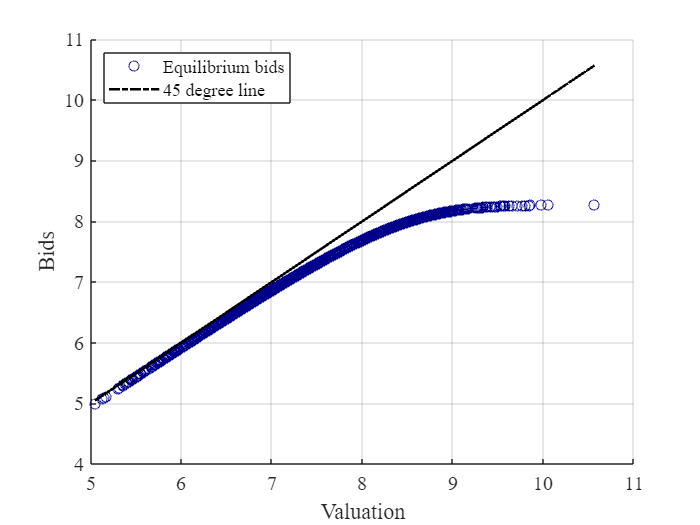

scatter(value_draws(:),bids); xlabel('Valuation'); ylabel('Bids');
hold on;
plot(value_draws,value_draws,'-.k');
legend('Equilibrium bids','45 degree line','location','northwest')
hold off;

This is what we expect: bids are below valuations, and the "markup" from bidders is greater the higher their valuation.

## 3. Identification and estimation of the distribution of valuations from bidding data

Using the auction bidding model and associated equilibrium bidding function in Section 5.1 to identify and estimate the distribution of valuations is possible, but it requires more complicated numerical procedures to solve for equilibrium bidding functions for each candidate distribution $F$. This imposes a substantial computational burden on estimation  -- an in-depth treatment of these techniques can be found in Paarsch and Hong (2006) *An Introduction to the Structural Econometrics of Auction Data*. Instead, we can use the results of Guerre, Perrigne, and Vuong (2000), who establish that valuations can be directly estimated by using the observed bidding distribution. Their main insight was to recognize that the profit function can be expressed in terms of the bid distribution:


$$\pi(b_k | v_1)  =  \mbox{Pr}(b_k > b_i \ \forall \ i =1,2,..,N) \times (v_k - b_k) \\
\qquad \quad \    = \ G(b_k)^{N-1}(v_k - b_k) $$


where $G(\cdot)$ is the cdf for the distribution of *bids*. Because the winning probability is the probability that a bid is higher than all other bids, and valuations (and therefore bids) are i.i.d., this probability can be expressed as $G(b_k)^{N-1}$, which is the probability that bid $b_k$ is greater than $N-1$ other draws from the bid distribution. Taking the first-order condition of this equation with respect to $v_k$ and re-arranging yields that

$v_{k} = b_{k} + \frac{G(b_{k})}{(N-1)g(b_{k})}$.

where $g(\cdot)$ is the bid density function. With this representation of valuations, we can estimate the distribution of valuations directly using the observed bids and estimates for the distribution and density functions of bids.

#### Review of non-parametric estimation

One of the advantages of this model is that it allows for very flexible estimation of demand, which in this setting is equivalent to the distribution of valuations. Because we can express a point-estimate of valuations in terms of distributions, we can specify these distributions fully non-parametrically. We need to estimate both the distribution function and the density function. Estimating the distribution function non-parametrically is easy. Suppose we have a sample $x_1,...,x_n$of $n$ points that are i.i.d. draws from a distribution $F$. The empirical cdf $\hat{F}$ for the distribution function is given by


$$\hat{F}(x) = \frac{1}{N} \sum_{n=1}^N 1\{x_{n} \leq x\}$$


so that $\hat{F}(x)$ is simply the fraction of the sample that is less than $x$.

Estimating the density requires a little more care. Among the most popular methods for implementing density estimation is kernel density estimation, which uses a kernel function to smooth over the data points present in the sample. Suppose we want to estimate the density function $f$ at a particular point $x$. The standard kernel density estimator for a sample of $n$ i.i.d. draws $x_1,...,x_n$ is given by


$$\hat{f}(x) = \frac{1}{nh} \sum_{i=1}^n K\left(\frac{x - x_i}{h} \right)$$


where $K(\cdot)$ is a kernel function that weights different observations $x_i$ by their distance to $x$ and $h$ is the bandwidth, a smoothing parameter that determines how much points "far away" from $x$ should be valued. Often, a normal kernel is used, meaning that $K(\cdot)$is the standard normal density function so that the kernel weight for observation $x_i$ is given by

$K\left(\frac{x - x_i}{h}\right) = \frac{1}{\sqrt{2\pi}} \exp\left(\frac{-(x- x_i)^2}{2h^2}\right)$.

When the bandwidth parameter $h$ is very small, then only points that are very close to $x$ will receive a significant weight. To see this, note that if $h$ is very small and $x - x_i >0$, then the argument into the normal density will be very large. The standard normal density evaluation at a point far away from zero is very small, so the resulting kernel weight for $x_i$ will be very small. However, if $x - x_i \approx 0$, then the kernel weight will be much higher as the low bandwidth parameter won't be enough to push the argument far away from zero. The result of this is that a low value for the bandwidth parameter is prone to *over-fitting *that generates a very jumpy estimate for the density that will match the particular idiosyncrasies of the sample too closely*.* Conversely, a very large value for $h$ will generate *over-smoothing* that provides too much weight to extremal points, flattening regions that should have high density and putting too much weight into the tails of the distribution. To see this effect, consider the following example of 250 random draws from a standard normal distribution.

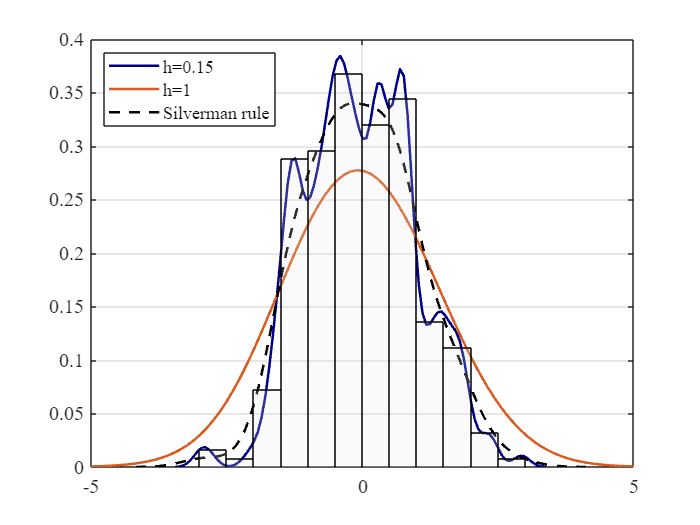

test_draws = randn([250,1]);
ksdensity(test_draws,'Bandwidth',0.15);
hold on
ksdensity(test_draws,'Bandwidth',1);
[f,x]=ksdensity(test_draws);
plot(x,f,'--k');
h=histogram(test_draws,'Normalization','pdf');h.FaceColor=[0.9,0.9,0.9];h.FaceAlpha=0.2;
xlim([-5,5]);
hold off;
legend('h=0.15','h=1','Silverman rule','location','northwest')

The random draws are fit to three different bandwidths. The first, $h=0.15$, clearly results in over-fitting, as the resulting density estimate is far too jumpy and attempts to match each "lump" in the histogram too closely. When $h=1$, the density is over-smoothed, with not enough weight given to the middle points in the distribution. However, an appropriately chosen bandwidth allows for the standard normal density to be matched quite closely; in this case, the bandwidth is chosen by heuristic known as *Silverman's rule-of-thumb*.

As should be evident from the figure above, choosing the bandwidth parameter appropriately is very important in getting accurate estimates for the density. A variety of methods for bandwidth parameter choice are available -- see Chapter 2 of Pagan and Ullah *Nonparametric Econometrics* for more discussion on bandwidth selection and the association bias-efficiency tradeoff. Often, however, default bandwidth values is statistics packages will use the bandwidth parameter that has been shown to be optimal (in the sense of minimizing mean squared error) when the underlying distribution generating the data is normal. This value is known as Silverman's rule-of-thumb and is given by $h = \left(\frac{4 \hat{\sigma}^5}{3n} \right)^{1/5}$ where $n$ is the sample size and $\hat{\sigma}$ is the sample standard deviation. This is the default bandwidth used by Matlab.

**Estimating bid distribution and density functions.**

With estimators defined for the distribution and density, we are ready to estimate the distribution of bids. Suppose we have data for $N$ bidders across $T$ auctions. The estimates for the distribution $G(\cdot)$ and density $g(\cdot)$ of bids are given by

$\hat{G}(b) = \frac{1}{NT} \sum_{n=1}^N \sum_{t=1}^T 1\{b_{nt} \leq b\}$,

$\hat{g}(b) = \frac{1}{NT\times h} \sum_{n=1}^N \sum_{t=1}^T K\left( \frac{b-b_{nt}}{h}\right)$.

Luckily for us, Matlab (and practically every other programming language) has built-in commands for this estimation:

[G,X] = ecdf(bids); % Empirical cdf
g = ksdensity(bids,X); % Kernel density estimation of pdf

Next, we plug the distribution and density of bids into the first-order condition:


$$\hat{v}_{nt} = b_{nt} + \frac{\hat{G}(b_{nt})}{(N-1)\hat{g}(b_{nt})}$$


pseudo_values = X + G./((N-1).*g);

Finally, we estimate the distribution of valuations using the same non-parametric density estimation techniques


$$\hat{f}(v) =  \frac{1}{NT \times h} \sum_{n=1}^N \sum_{t=1}^T  K \left( \frac{v - \hat{v}_{nt}}{h} \right)$$


Again, we can use the built-in Matlab command "ksdensity" to make this easy:

[f,v] = ksdensity(pseudo_values);

Finally, let's compare the estimated distribution to the actual distribution:

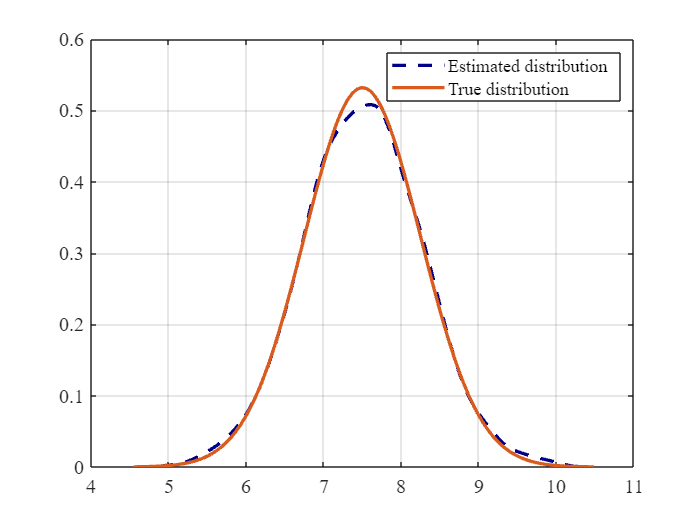

plot(v,f,'--',v,pdf(BuyerValueDist,v),'-','LineWidth',2);
legend('Estimated distribution','True distribution')

As we can see, the estimated distribution fits the true distribution almost exatly.

#### Semi-parametric estimation

Instead of doing fully non-parametric estimation, we can also fit the distribution of bids and the distribution of pseudo-values to a parametric distribution, like the Normal, Log-Normal, or Exponential distributions. This has the advantage of requiring less data, although the estimation will not be as flexible as a non-parametric approach.

To illustrate, let's apply this estimation to only the last stage: recovering the distribution of valuations from the pseudo-values $\hat{v}$. Let's suppose we choose a Normal distribution as the distribuition of $v$

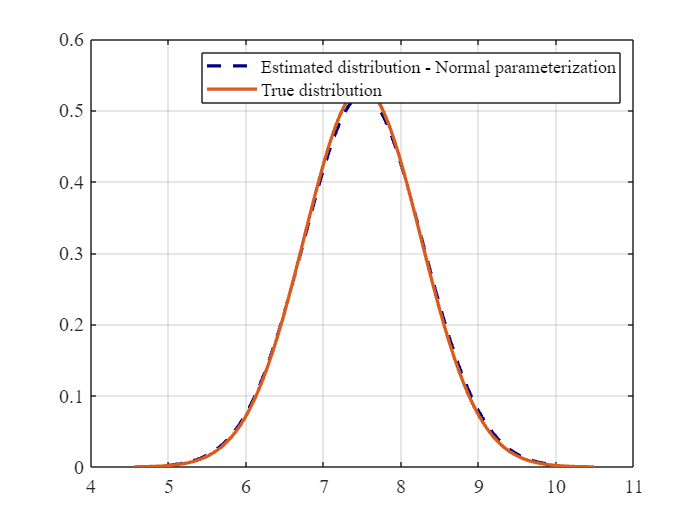

log_likelihood = @(theta) (-1)*sum(log(normpdf(pseudo_values,theta(1),theta(2)))); % defines the log-likelihood function; we use a (-1) because by default Matlab finds minimums, not maximums.
[theta_hat,lik_val] = fminsearch(log_likelihood,[mu_b-1,sigma_b+0.25]);
w=linspace(5,10,100);
plot(w,normpdf(w,theta_hat(1),theta_hat(2)),'--',v,pdf(BuyerValueDist,v),'-','LineWidth',2);
legend('Estimated distribution - Normal parameterization','True distribution')

This looks great! However, suppose that we "guessed wrong" with the distribution and chose a Weibull distribution instead:

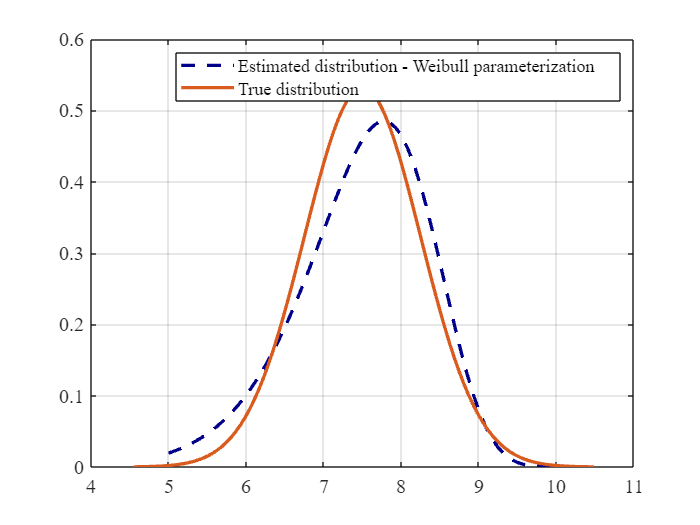

log_likelihood2 = @(theta) (-1)*sum(log(wblpdf(pseudo_values,theta(1),theta(2))));
[theta_hat,lik_val] = fminsearch(log_likelihood2,[2,0.3]);
w=linspace(5,10,100);
plot(w,wblpdf(w,theta_hat(1),theta_hat(2)),'--',v,pdf(BuyerValueDist,v),'-','LineWidth',2);
legend('Estimated distribution - Weibull parameterization','True distribution')

Now it doesn't look so great. Using a parametric distributional assumption is a trade-off between ease-of-use/lower data requirements on the one hand and flexibility in fitting the "true" underlying distribution on the other hand.

## 4. Performing policy analysis

We need to simulate one extra piece of data to perform our policy analysis: the reserve rate and the number of auctions that were successful (i.e. had a highest bid above the reserve).

Recall that we are assuming that the reserve price is zero. To find the optimal reserve (see Krishna (2009) *Auction Theory*), we solve for $r^*$ such that 


$$r^* = v_s + \frac{1-F(r^*)}{f(r^*)}$$


Let's assume that $v_s=7$, i.e. that the seller's valuation for the property is always $700,000. Then we find the reserve as follows:

reserve_fun = @(r) r -7 - (1-cdf(BuyerValueDist,r))./pdf(BuyerValueDist,r); % I have "cheated" a bit here by using the true distribution instead of the estimated distribution for buyer values
r_star = fsolve(reserve_fun,0.6); % finds the roots/zeros of "reserve_fun"


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Now we simulate the effects of setting an optimal reserve price on the expected revenue obtained by the seller. We start by re-simulating equilibrium bids, but this time with the reserve

B_res = @(V) arrayfun(@(v) v - ((1./cdf(BuyerValueDist,v)).^(N-1)).*integral(@(u)cdf(BuyerValueDist,u).^(N-1),r_star,v),V);
V = value_draws(:);
bids_res = zeros(size(V,1),1); 
bids_res(V>=r_star) = B_res(V(V>=r_star)); % only bidders with values greater than the reserve submit a bid
bids_by_auc_res = sort(reshape(bids_res,[1000,N]),2,'descend');

bids_by_auc = sort(reshape(bids,[1000,N]),2,'descend');

seller_profit_res = mean(max(7,bids_by_auc_res(:,1)) - 7);
seller_profit = mean(bids_by_auc(:,1) - 7);
ProfitDiff = seller_profit_res - seller_profit

ProfitDiff = 0.0408

The implementation of the optimal reserve price has increased expected seller profit by about $4,080 dollars. In this case, the profit improvement is rather modest (about 4.5%), as with high $N$ the probability of a maximum bid significantly above the seller's valuation is already quite high. Try re-running the code with $N=3$ (on line 6) and see what the improvement looks like then.

We might be concerned that much of this profit improvement is from sellers being forced to sell at a loss in the original auction environment, as we have assumed that the house is sold to the highest bidder regardless of whether the highest bid exceeds the seller's valuation of 7. However, we can quickly check that this is not often the case:

num_profit_loss = sum(bids_by_auc(:,1)<7)

num_profit_loss = 2

This means only two auctions resulted in negative profit for the seller in the original sample. The vast majority of the imrovement is coming from sales occuring at much higher prices due to the reserve price.

To further visualize this, we can plot the distributions of the highest bids with and without the optimal reserve price:

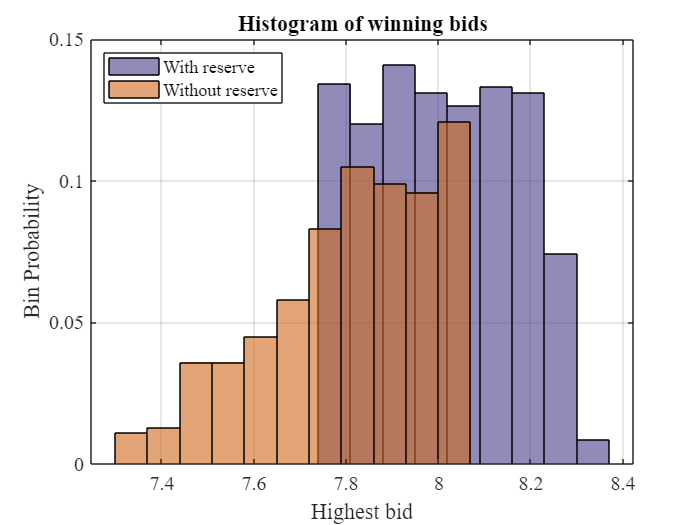

h2=histogram(bids_by_auc_res(bids_by_auc_res(:,1)>0,1),'BinEdges',7.6:0.07:8.4); h2.FaceAlpha=0.6;h2.FaceColor = [0.2812    0.2383    0.5430]; h2.Normalization = 'probability';
hold on
h1=histogram(bids_by_auc(:,1),'BinEdges',7.3:0.07:8.1); h1.FaceColor = [0.8203    0.4102    0.1172]; h1.Normalization = 'probability';
hold off;
legend('With reserve','Without reserve','location','northwest');
xlabel('Highest bid');ylabel('Bin Probability'); title('Histogram of winning bids');

Clearly the distribution of successful bids has been pushed much higher due to the reserve. However, the reserve also generates failed auctions, as in some cases no buyer will have a valuation exceeding the reserve. 

no_sale_pct = mean(bids_by_auc_res(:,1)==0)

no_sale_pct = 0.0840

This means a sale will not occur in 8.4% of auctions after the reserve price is implemented. Of course, the increase in profits conditional on sale still makes the reserve a net benefit for the seller.

## 5. Estimation when only the winning bid is observed

In practice, it is extremely common to observe only the winning bid and the total number of bidders when working with auction data. Because of this, it is necessary for our estimation strategy to handle these cases as well. When dealing with the IPV case, we can use the result that when random variables are i.i.d. draws from a distribution with cdf $F$, then there is a monotonic mapping from the distribution function of any order statistic $(i:n)$, or the $i$-th highest draw from a set of $n$ draws


$$F^{(i:n)}(s) = \frac{n!}{(n-i)!(i-1)!} \int_0^{(F(s)} t^{i-1}(1-t)^{n-i} dt$$


This equation means that observing any order statistic from the auction results is sufficient to identify the distribution of valuations: we can observe the lowest bid in each auction, the third highest bid in each auction, or any other order statistic, and the identification of the distribution will not be affected.

To begin, let's re-draw our valuations from the same normal distribution.

mu_b = 7.5; % Average bidder's home valuation, in $100,000's.
sigma_b = 0.75; % Standard deviation of bidder valuation distribution.
BuyerValueDist = makedist('Normal','mu',mu_b,'sigma',sigma_b); % Assume a normal distribution for valuations

num_auc = 1000; % Simulate 2000 auctions
N=5; % Assume two bidders at each auction
rng(21);
B = @(V) arrayfun(@(v) v - ((1./cdf(BuyerValueDist,v)).^(N-1)).*integral(@(u)cdf(BuyerValueDist,u).^(N-1),0,v),V);
% Draw valuations from the distribution defined above:
value_draws = random(BuyerValueDist,[num_auc,N]);



### Second-price

In second-price auctions in which only the transaction price is observed, the econometrican observes the second highest bid, or $b^{(n-1:n)}$.


$$F_{V}^{(N-1:N)}(w) =N(N-1) \int_0^{ F_V(w)} t^{N-2} (1-t) dt$$


In practice, it is simpler to work with the following, equivalent expression in computation:


$$F_{V}^{(N-1:N
)}(w) = \sum_{j=N-1}^N {N \choose j} F_V(w)^j\big[1-F_V(w)\big]^{N-j} = N F_V(w)^{N-1} \big[1-F_V(w)\big] + F_V(w)^N \\ \Rightarrow \quad F_V^{(N-1:N)}(w) = NF_V^{N-1}(w) - (N-1)F_V^N(w)$$


This gives us the equations we need to transform the observed transaction prices into estimates of the cdf $F_V$.

In fact, we can exploit the polynomial structure of the equation to use polynomial root finding algorithms instead of general non-linear equation solvers. Our estimate for $F_V(w)$ is the (unique) root in (0,1) of $\lambda_w(Z)$ defined by


$$(N-1)Z^N- NZ^{N-1}+ F_V^{(N-1:N)}(w) = 0$$


For example, if $N=2$, then $\hat{F}_V(w) = 1 - \sqrt{1-F_V^{(N-1:N)}(w)}$.

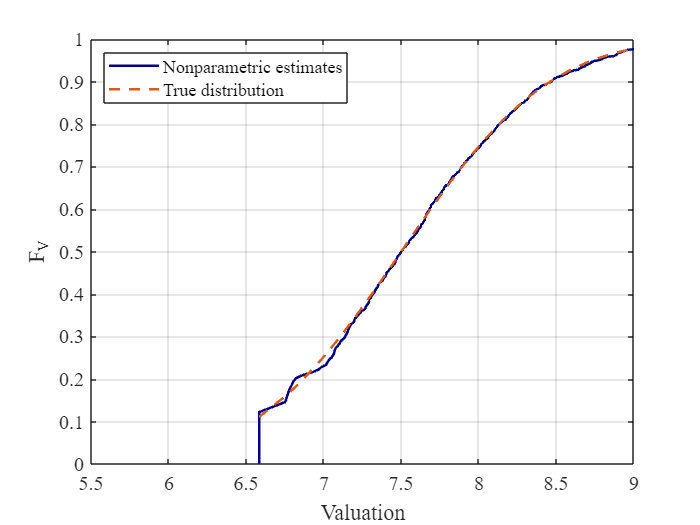

WBids_second=sort(value_draws,2,'descend');
WBids_second=WBids_second(:,2);

[F_V2,X_V2]=ecdf(WBids_second);
F_V=zeros(size(F_V2));

for j=1:length(X_V2)
    gap = zeros(1,N-2);
    poly_vec = [(N-1), -N, gap, F_V2(j)];
    try
        F_set = roots(poly_vec); % Find all roots of the polynomial lambda(Z)
        F_V(j) = F_set(F_set >= 0 & F_set<=1); % Pick the (unique) real root in (0,1)
    catch
        if j==1
            F_V(j)=0;
        else
            F_V(j) = F_V(j-1);
        end
    end
end

plot(X_V2,F_V,'-',X_V2,normcdf(X_V2,mu_b,sigma_b),'--');
xlim([5.5,9]);
xlabel('Valuation');
ylabel('F_V');
legend('Nonparametric estimates','True distribution','location','northwest');

We can also estimate the distribution parametrically. This involves using the likelihood of observing each transaction price $w$ as a function of the overall valuation distribution    


$$f_{V}^{(N-1:N)}(w) = N(N-1) F_V(w)^{N-2} \big[1-F_V(w)\big]f_v(w)$$


This equation states that there are $N(N-1)$ different ways for $N-2$ bidders to have a valuation strictly less than the winning bid (i.e., $F_V(w)^{N-2}$), while one bidder has a valuation exactly equal to the winning bid (i.e., $f_v(w)$), and the winning bidder's valuation exceeds the highest bid/second highest valuation $1-F_V(w)$.

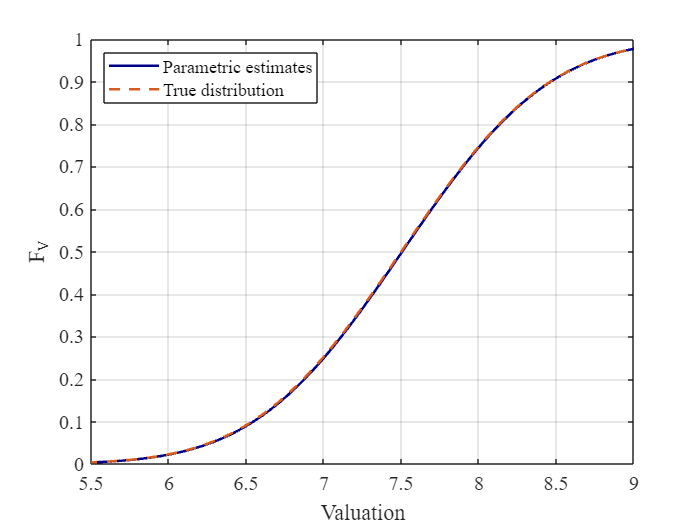


second_price_like = @(theta) -sum(log(N*(N-1)*normcdf(WBids_second,theta(1),theta(2)).^(N-2).*(1-normcdf(WBids_second,theta(1),theta(2))).*normpdf(WBids_second,theta(1),theta(2))));
[theta_hat_second,~]=fminunc(second_price_like,[5,1],optimoptions('fminunc','Display','none'));

plot(v,normcdf(v,theta_hat_second(1),theta_hat_second(2)),'-',v,normcdf(v,mu_b,sigma_b),'--');
xlim([5.5,9]);
xlabel('Valuation');
ylabel('F_V');
legend('Parametric estimates','True distribution','location','northwest');

## 6. Moving away from the "sealed bid abstraction": ascending auctions as a dynamic game

Many auction formats used in practice are ascending auctions, in which the highest bid increases over time and bidders have the opportunity to react by raising their own bid or exiting the auction. Structural auction models routinely assume that these dynamic auctions are strategically equivalent to sealed-bid formats. For example, English auctions are open-cry ascending bid auctions, meaning that participating bidders place bids with the auctioneer that gradually raises the price. In taking data from such environments to a model, econometricians commonly assume that the English auction functions as a button auction as in Milgrom and Weber (1982), in which the price increases exogenously and private valuation bidders have a dominant strategy of remaining in the auction until the price exceeds their valuation. Button auctions are strategically equivalent to second price sealed bid auctions, and if the assumption that bidding in English auctions approximates a button auction, then we can use sealed-bid techniques to identify and estimate the distribution of valuations.

In practice, however, we may encounter bid data that does not appear to be consistent with the button auction framework. One stylized example is presented below for an auction that occurs over one minute:

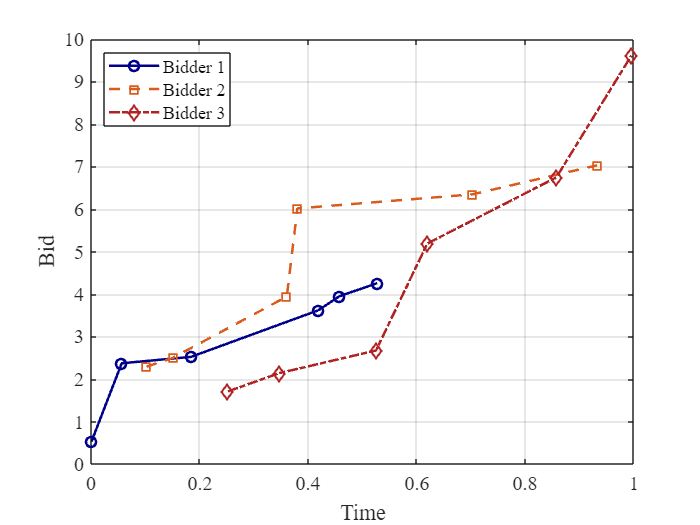

t=sort(rand([3,6]),2);
b=sort(3+normrnd(1,2,[3,6]),2);
plot(t(1,:),b(1,:),'-o',t(2,:),b(2,:),'--s',t(3,:),b(3,:),'-.d');
legend('Bidder 1','Bidder 2','Bidder 3','location','northwest');
xlabel('Time');ylabel('Bid')

Here we see "jump bidding", particularly by Bidder 3, that does not appear to be in line with the button auction model. In particular, it seems as though Bidder 3 could have won at a much lower price (perhaps $5.50), but instead paid over $9. 

One early approach at handling this type of situation was presented by Haile and Tamer (2003). Their framework does not fully specify the auction as a game, and therefore does not have equilibrium bid predictions, but instead imposes two behavioral assumptions on bidding:

- Bidders do not bid more than they are willing to pay, and

- Bidders do not let an opponent win at a price they are willing to beat.

These assumptions permit the construction of upper and lower bounds on the distribution of valuations $F_V$, with Assumption 1 providing a lower bound (the highest bid submitted by each bidder $i$ satisfies $\overline{b}_i \leq v_i$), while Assumption 2 provides an upper bound with the additional assumption that there exists a minimum bid increment $\Delta$. A simple version of the bounds is implemented below, using the same bidding data as in the second-price example:

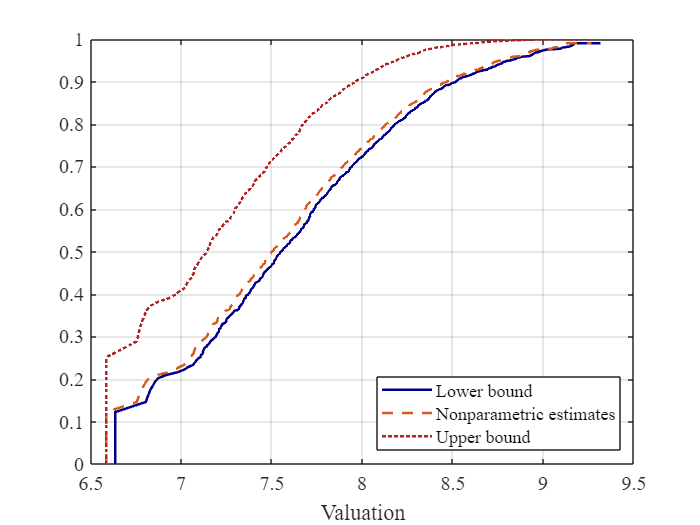


% Haile and Tamer (2003) bounds

delta=0.05;

Z=sort(value_draws,2,'descend');
Z_B=Z(:,2)+delta;

[G_delta,X_delta]=ecdf(Z_B);
F_L=zeros(size(G_delta));



for j=1:length(X_V2)
    gap = zeros(1,N-2);
    poly_vec = [(N-1), -N, gap, G_delta(j)];
    try
        F_set = roots(poly_vec); % Find all roots of the polynomial
        F_L(j) = F_set(F_set >= 0 & F_set<=1); % Pick the (unique) real root in (0,1)
    catch
        if j==1
            F_L(j)=0;
        else
            F_L(j) = F_L(j-1);
        end
    end
end

[G_N,X_N]=ecdf(Z(:,2));
F_U=G_N.^(1/N);

plot(X_delta,F_L,'-',X_V2,F_V,'--',X_N,F_U,':');
legend('Lower bound','Nonparametric estimates','Upper bound','location','southeast');
xlabel('Valuation');

Another approach is to assume that bidders cannot perfectly monitor the auction. Perhaps the opportunity cost of their time is too great to perfectly keep track of all submitted bids, generating rational inattention, or it takes a finite amount of time to submit a bid so bidders can only respond finitely often. This approach has been taken by Barkley et al (2021) and Cho et al (2022). It retains Assumption 1 of Haile and Tamer (2003) that bidders do not bid above their valuation, but permits their Assumption 2 to not hold -- bidders may want to submit a bid higher than the current winning bid, but may not have the opportunity to do so because of inattention. In a future lecture, we will discuss estimation in this framework in greater detail.

## Exercise: estimating first-price sealed bid auctions when only the winning bid is available

Simulate $T=5000$ first-price sealed bid auctions with $N=2$ bidders at each auction and no binding reserve price using the bid function defined above. Assume that buyer values are drawn from the same distribution $N(7.5, 0.5)$ used in previous sections. 

Estimate the cdf $F_v$ under the assumption that only the winning bid is observed using the fact that $H^{(n:n)}(v) = \big[ H(v) \big] ^n$, where $H^{(n:n)}$ is the distribution of the highest draw from $n$ draws of the distribution $H$.

% Exercise code and output here



## References

Athey, S., & Haile, P. A. (2002). [Identification of standard auction models](https://citeseerx.ist.psu.edu/document?repid=rep1&type=pdf&doi=05fde8049139f504435868c89f2d46edec8cf6e9). *Econometrica*, *70*(6), 2107-2140.

Athey, S., & Haile, P. A. (2007). [Nonparametric approaches to auctions](https://citeseerx.ist.psu.edu/document?repid=rep1&type=pdf&doi=7527a28265798b68d062a78dfed60b01249c5352). *Handbook of econometrics*, *6*, 3847-3965.

Barkley, A., Groeger, J. R., & Miller, R. A. (2021). [Bidding frictions in ascending auctions](https://www.sciencedirect.com/science/article/pii/S0304407620303250). *Journal of Econometrics*, *223*(2), 376-400.

Freyberger, J., & Larsen, B. J. (2022). [Identification in ascending auctions, with an application to digital rights management](https://onlinelibrary.wiley.com/doi/pdf/10.3982/QE1151). *Quantitative Economics*, *13*(2), 505-543.

Gallant, A. R., & Nychka, D. W. (1987). [Semi-nonparametric maximum likelihood estimation](https://www.jstor.org/stable/1913241). *Econometrica: Journal of the econometric society*, 363-390.

Guerre, E., Perrigne, I., & Vuong, Q. (2000). [Optimal nonparametric estimation of first‐price auctions](https://kylewoodward.com/blog-data/pdfs/references/guerre+perrigne+vuong-econometrica-2000A.pdf). *Econometrica*, *68*(3), 525-574.

Haile, P. A., & Tamer, E. (2003).[ Inference with an incomplete model of English auctions](https://www.journals.uchicago.edu/doi/full/10.1086/344801?casa_token=tLcR_jQ0qXIAAAAA:sCBBwxpuyr3hjQTeXLaXawS2M6QQXaiL4LwW41z296w5n1d91PQ71nOGD7VWlHqaRIg52N5_oX4). *Journal of Political Economy*, *111*(1), 1-51.

Cho, S. J., Paarsch, H. J., & Rust, J. (2022). [Explaining Early Bidding in Informationally-Restricted Ascending-Bid Auctions](https://editorialexpress.com/cgi-bin/conference/download.cgi?db_name=IIOC2023&paper_id=4). Working paper.